北邮版《微波技术基础》课件 插图代码

第2章 fig2.1

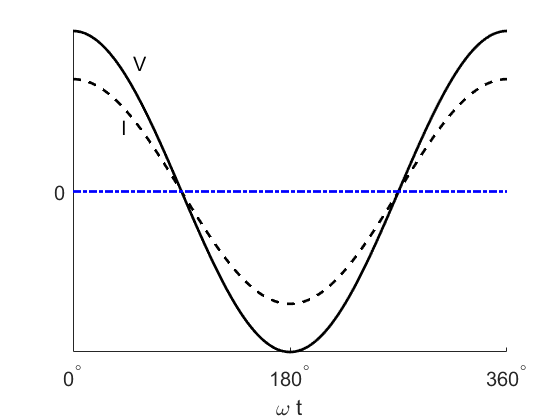

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,0.4,'I','FontSize',15)
axis tight
box off

fig 2.2

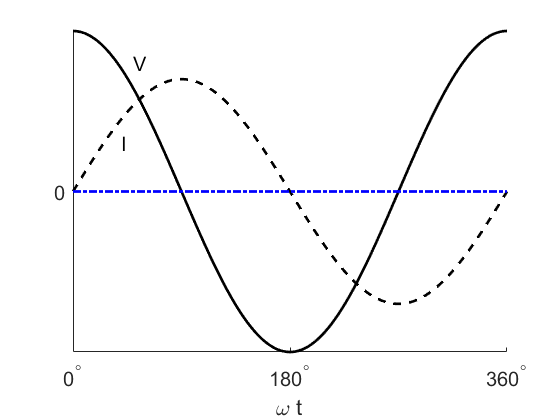

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x-90)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,0.3,'I','FontSize',15)
axis tight
box off

fig 2.3

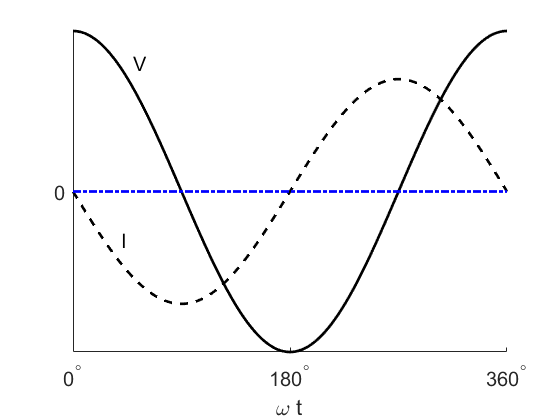

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x+90)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,-0.3,'I','FontSize',15)
axis tight
box off

fig 2.8

clear all
close all
x = 0:1:360;
y1 = cosd(4*x);
y2 = cosd(4*x-30)*0.3;
y3 = y1.*y2;
y4 = 0.5*0.3*ones(1,length(x));
plot(x,y1,'k--',x,y2,'k-.',x,y3,'k-',x,y4,'b:','LineWidth',2);
xlabel('t')
set(gca,'FontSize',15)
set(gca,'XTick',[])
set(gca,'YTick',[])
text(20,0.9,'v(t)','FontSize',15)
hold on;plot([10,20],[0.8,0.85],'k')
text(80,-0.4,'i(t)','FontSize',15)
plot([50,80],[-0.3,-0.4],'k');plot([100,135],[-0.4,-0.3],'k')
text(100,4*max(abs(y3)),'p(t)=v(t)i(t)','FontSize',15);plot([135,135],[1.1*max(abs(y3)),3.5*max(abs(y3))],'k')
text(360,3*max(abs(y4)),'P_{av}','FontSize',15);plot([345,360],[max(abs(y4)),3*max(abs(y4))],'k')
axis tight
box off

fig 2.9

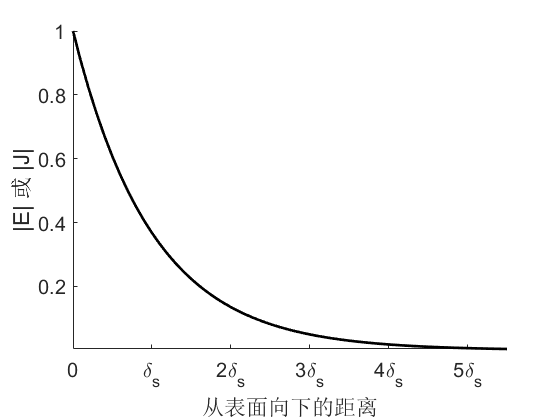

clear all
close all
z = 0:.1:5.5;
J = exp(-z);
plot(z,J,'k-','LineWidth',2)
set(gca,'FontSize',15)
set(gca,'XTick',[0,1,2,3,4,5]);
set(gca,'XTicklabel',{'0','\delta_s','2\delta_s','3\delta_s','4\delta_s','5\delta_s'})
xlabel('从表面向下的距离')
ylabel('|E| 或 |J|')
xlim([-0.3 5.5]);ylim([-0.1 1.1])
axis tight
box off

fig 4.20

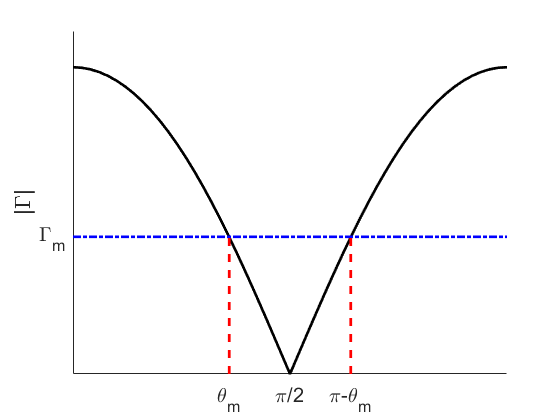

zl = 100+1i*50;
z0 = 50;
theta = 0:pi/50:pi;
absGamma = abs(1./sqrt(1+(4*z0*zl/(zl-z0)^2)*(sec(theta)).^2));
plot(theta,absGamma,'k-',theta,0.2*ones(1,length(theta)),'b-.','LineWidth',2);hold on
plot(ones(1,10)*1.13097,linspace(0,0.2,10),'r--',ones(1,10)*2.01062,linspace(0,0.2,10),'r--','LineWidth',2);
set(gca,'FontSize',15)
set(gca,'XTick',[1.13097,pi/2,2.01062]);
set(gca,'XTicklabel',{'\theta_m','\pi/2','\pi-\theta_m'})
set(gca,'YTick',[0.2]);
set(gca,'YTicklabel',{'\Gamma_m'})
ylabel('|\Gamma|')
box off

fig 4.30

z0 = 75;zl = 100+1i*80;
sm1 = smithchart;ax = gca; hold all;
gamma_zl=(zl-z0)/(zl+z0);
gamma_yl = -gamma_zl;y0 = 1/z0;yl=y0*(1-gamma_yl)/(1+gamma_yl)

yl = 0.0178 + 0.0142i

Smith_plotGammaCircle(ax,zl,z0);

sub_hp2 =   Line - 属性:

              Color: [1 0.2000 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  显示 所有属性


x_data =     0.4356    0.4347    0.4322    0.4279    0.4219    0.4143    0.4050    0.3941    0.3817    0.3678    0.3524    0.3356    0.3175    0.2982    0.2777    0.2560    0.2334    0.2098    0.1855    0.1604    0.1346    0.1083    0.0816    0.0546    0.0274   -0.0000   -0.0274   -0.0546   -0.0816   -0.1083   -0.1346   -0.1604   -0.1855   -0.2098   -0.2334   -0.2560   -0.2777   -0.2982   -0.3175   -0.3356   -0.3524   -0.3678   -0.3817   -0.3941   -0.4050   -0.4143   -0.4219   -0.4279   -0.4322   -0.4347


y_data =          0    0.0274    0.0546    0.0816    0.1083    0.1346    0.1604    0.1855    0.2098    0.2334    0.2560    0.2777    0.2982    0.3175    0.3356    0.3524    0.3678    0.3817    0.3941    0.4050    0.4143    0.4219    0.4279    0.4322    0.4347    0.4356    0.4347    0.4322    0.4279    0.4219    0.4143    0.4050    0.3941    0.3817    0.3678    0.3524    0.3356    0.3175    0.2982    0.2777    0.2560    0.2334    0.2098    0.1855    0.1604    0.1346    0.1083    0.0816    0.0546    0.0274


Smith_plotRefLine2PhaseCircle(ax,zl,z0);
Smith_plotOpRefLine2PhaseCircle(ax,zl,z0);

gamma_L = 0.2910 + 0.3241i

a = 0.8391

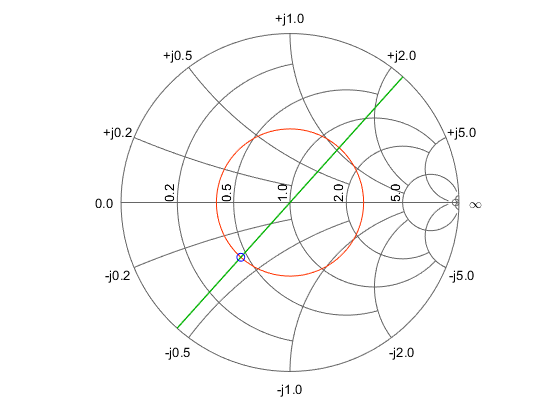

plot(ax,real(gamma_yl),imag(gamma_yl),'bo');hold off

homework 2.3

syms t
fA = 2*cosd(6*t+120)+4*sind(6*t-60);
fB = 2*sqrt(5)*cosd(6*t+3.43);
expand(fA)

$$ans = 2\,\sin\left(\frac{\pi \,t}{30}\right)-\cos\left(\frac{\pi \,t}{30}\right)-2\,\sqrt{3}\,\cos\left(\frac{\pi \,t}{30}\right)-\sqrt{3}\,\sin\left(\frac{\pi \,t}{30}\right)$$

expand(fB)

$$ans = 2\,\sqrt{5}\,\cos\left(\frac{343\,\pi }{18000}\right)\,\cos\left(\frac{\pi \,t}{30}\right)-2\,\sqrt{5}\,\sin\left(\frac{343\,\pi }{18000}\right)\,\sin\left(\frac{\pi \,t}{30}\right)$$

homework 2.8

（1）

syms t
v1 = 2-4*cos(2*t);v2 = 3*sin(pi*t)+2*cos(pi*t);v3 = 2*cos(2*t)+4*cos(2*t+pi/4)+12*sin(2*t);
v1_square = v1^2;v2_square = v2^2;v3_square = v3^2;
ans1 = sqrt(int(v1_square,0,360)/360)

$$ans1 = \sqrt{\frac{\sin\left(1440\right)}{180}-\frac{\sin\left(720\right)}{45}+12}$$

ans2 = sqrt(int(v2_square,0,2)/2)

$$ans2 = \frac{\sqrt{2}\,\sqrt{13}}{2}$$

ans3 = sqrt(int(v3_square,0,2*pi)/2/pi)

$$ans3 = \sqrt{2}\,\sqrt{41-10\,\sqrt{2}}$$

（2）

fig 6.10 绘出圆波导H11的场分布图

clc;
clear all;
close all;
a = 20;
m = 0;
n = 1;

if m==0
    ki_m = 1;
else
    ki_m = sqrt(2);
end

r = 0:0.1:a;
J0 = besselj(0,r);
x_mn = roots(J0);
k_mn = x_mn./a;
F_mn = (ki_m*k_mn)./(J0(x_mn).*sqrt(pi*(x_mn.^2-m^2)));

数组索引必须为正整数或逻辑值。


for r=0:1:a
    for phi=0:pi/180:2*pi
        e_mnR = -F_mn.*(J0(k_mn*r)/(k_mn.*r))*sin(m*phi);
        e_mnPHI = F_mn.*J0(k_mn*r)*cos(m*phi);
    end
end

e_mnR = abs(e_mnR);
e_mnPHI = abs(e_mnPHI);
x = 0:1:a;
[X,Y] = meshgrid(1:1:a);
quiver(X,Y,e_mnR,e_mnPHI);
hold on

fig 6.x 衰减系数随频率变化图

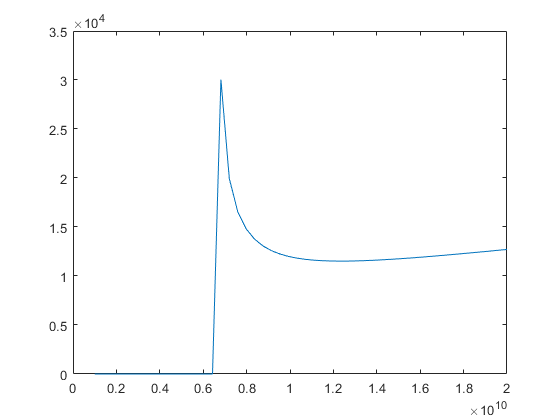

a = 2.286e-2;
b1 = 0.5*a;
b2 = 0.1*a;
C=3e8;
f = linspace(1e9,20e9,50);
lambda=C./f;
alpha1 = (1.9e-4)*sqrt(f)/b1.*(1+2*b1/a*(lambda/2/a).^2)./sqrt(1-(lambda/2/a).^2);
alpha2 = (1.9e-4)*sqrt(f)/b2.*(1+2*b2/a*(lambda/2/a).^2)./sqrt(1-(lambda/2/a).^2);
plot(f,alpha2)

fig 6.x2

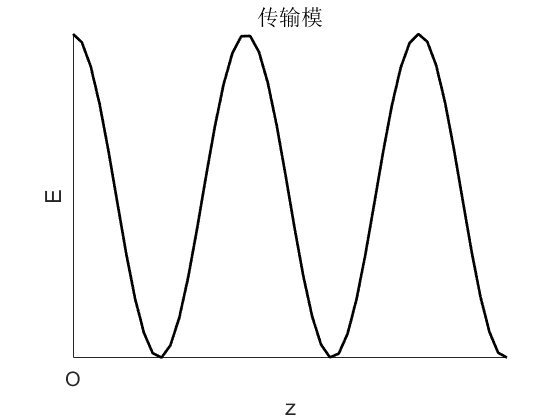

f = 10e9;
omega = 2*pi*f;
t = 1;
lambda1 = 3e-2;
lambda2 = 4.7e-2;
lambdaC = 4.56e-2;
beta = 2*pi/lambda1*sqrt(1-(lambda1/lambdaC)^2);
gamma = 2*pi/lambdaC*sqrt(1-(lambdaC/lambda2)^2);
z = linspace(0,10e-2,50);
y1 = cos(omega*t-beta*z);
y2 = exp(-gamma*z).*cos(omega*t-beta*z);
y3 = exp(-gamma*z);
plot(z,y1,'k-','Linewidth',2);
title('传输模')
xlabel('z');ylabel('E');
set(gca,'FontSize',15)
set(gca,'XTick',[0]);
set(gca,'XTicklabel',{'O'})
set(gca,'YTick',[]);
set(gca,'YTicklabel',{''})
xlabel('z');ylabel('E')
box off

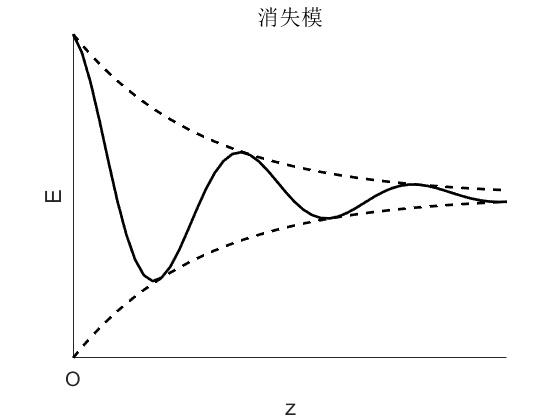

plot(z,y2,'k-','Linewidth',2);hold on;
plot(z,y3,'k--',z,-y3,'k--','Linewidth',2)
set(gca,'FontSize',15)
set(gca,'XTick',[0]);
set(gca,'XTicklabel',{'O'})
set(gca,'YTick',[]);
set(gca,'YTicklabel',{''})
title('消失模')
xlabel('z');ylabel('E')
box off

圆波导对应的第一类贝塞尔函数图形

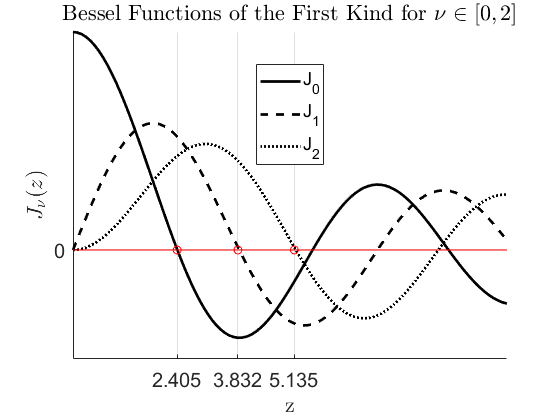

clear all;close all;
z = 0:0.1:10; %Define the domain.
% ================== Calculate the first five Bessel functions of the first kind ========= 
% ============= Each row of J contains the values of one order of the function ===========
% ====================== evaluated at the points in z ========================.
J = zeros(3,101);
for i = 0:2
    J(i+1,:) = besselj(i,z);
end
linestyle = ["k-","k--","k:"]; %字符串数组，使用双引号 ""
% Plot all of the functions in the same figure.
for ii=1:3
plot(z,J(ii,:),linestyle(ii),'LineWidth',2),hold on
end
plot(z,zeros(1,length(z)),'r-');
x1 = [2.4,3.8,5.1];y1 = [0,0,0];
plot(x1,y1,'ro')
grid on
set(gca,'FontSize',15)
legend('J_0','J_1','J_2','Location','Best')
title('Bessel Functions of the First Kind for $\nu \in [0, 2]$','interpreter','latex')
xlabel('z','interpreter','latex')
ylabel('$J_\nu(z)$','interpreter','latex')
set(gca,'XTick',[2.4,3.8,5.1]);
set(gca,'XTicklabel',{'2.405','3.832','5.135'})
set(gca,'YTick',[0])
set(gca,'YTicklabel',{0})
box off

第二类贝塞尔函数图形

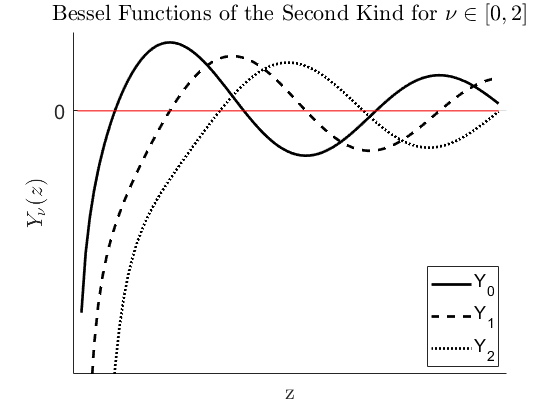

clear all;close all;
z = 0:.1:10;
Y = zeros(3,101);
for ii=0:2
    Y(ii+1,:) = bessely(ii,z);
end
linestyle = ["k-","k--","k:"];
for jj=1:3
    plot(z,Y(jj,:),linestyle(jj),'LineWidth',2),hold on
end
axis([-0.1 10.2 -2 0.6])
plot(z,zeros(1,length(z)),'r-');
grid on
set(gca,'FontSize',15)
legend('Y_0','Y_1','Y_2','Location','Best')
title('Bessel Functions of the Second Kind for $\nu \in [0,2]$','interpreter','latex')
xlabel('z','interpreter','latex')
ylabel('$Y_\nu(z)$','interpreter','latex')
set(gca,'XTick',[]);
set(gca,'XTicklabel',{''})
set(gca,'YTick',[0])
set(gca,'YTicklabel',{0})
box off

H11模 横截面上的场分布 Er随着phi变化的分布情况

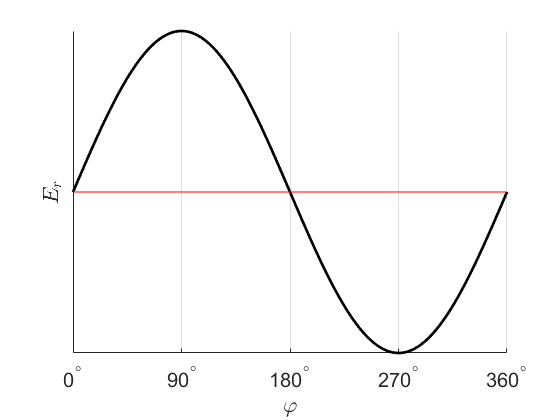

clear all;close all
phi = linspace(0,2*pi,361);
Er = sin(phi);
plot(phi,Er,'k-','LineWidth',2);hold on;
plot(phi,zeros(1,length(phi)),'r-');
grid on
set(gca,'FontSize',15)
xlabel('$\varphi$','interpreter','latex')
ylabel('$E_r$','interpreter','latex')
set(gca,'XTick',[0,pi/2,pi,3*pi/2,2*pi]);
set(gca,'XTicklabel',{'0^{\circ}','90^{\circ}','180^{\circ}','270^{\circ}','360^{\circ}'})
set(gca,'YTick',[]);
set(gca,'YTicklabel',{''})
box off